% Define harmonic coefficients
A_0 = [1.5 1; 1 -0.5];
A_1 = [-4/pi^2 1/2; 0 1/(pi*1i)];
A_2 = [0 0; 1i/2 0];
A_3 = [4/(3*pi)^2 0; 0 1/(pi*3*1i)];

% Create PhasorArray with all harmonics (negative to positive)
A = PhasorArray(cat(3,conj(A_3), conj(A_2), conj(A_1), A_0, A_1, A_2, A_3));
% Equivalently for real signal:
A = PhasorArray(cat(3, A_0, A_1, A_2, A_3),"isreal",true)

A = 2x2x7 PhasorArray of double representing a 2x2 real-valued periodic matrix with 3 harmonics

T = 1; %period
N = 6; %2^N points used for FFT 
At = @(t) [1+sawtooth(2*pi*t/T,0.5)+0.5, 1+cos(2*pi*t/T); 1-sin(2*2*pi*t/T), -0.5 + square(2*pi*t/T)/2];
A = PhasorArray.funcToPhasorArray(At,T,N)

A = 2x2x63 PhasorArray of double representing a 2x2 real-valued periodic matrix with 31 harmonics

% Harmonic spectrum visualization (stem plot)
figure 
stem(A,"scale","linear","uniformYLim",0)
sgtitle('stemplot of phasor of A(t)')

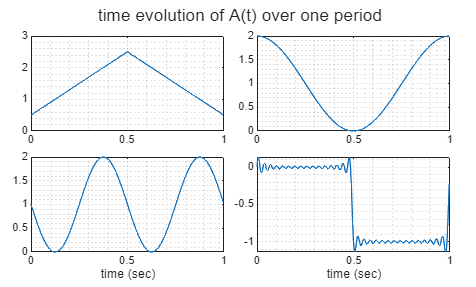


% Time-domain reconstruction over multiple periods
figure
plot(A)
sgtitle('time evolution of A(t) over one period')

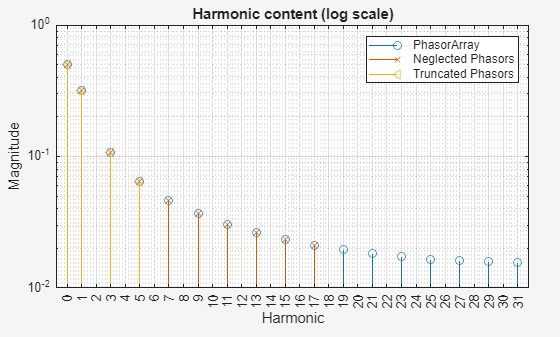

% Neglect small harmonics (threshold-based filtering)
A_neglect = neglect(A{2,2}, 2.e-2, 'reduceMethod', 'absolute');
% Truncate to fixed harmonic order
A_trunc = trunc(A{2,2}, 5);
figure
stem(A{2,2}, 'scale', 'log')
hold on
stem(A_neglect, 'Marker', 'x')
stem(A_trunc, 'Marker', '<')
legend('PhasorArray','Neglected Phasors','Truncated Phasors')
title('Harmonic content (log scale)')
xlabel('Harmonic'), ylabel('Magnitude')

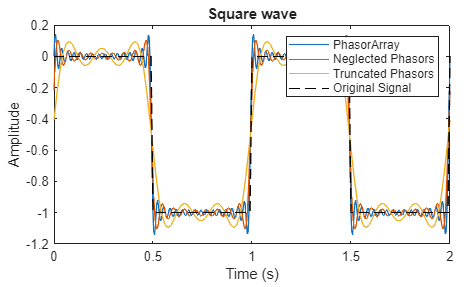

figure
plot(A{2,2}, T, [0, 2*T])
hold on
plot(A_neglect, T, [0, 2*T])
plot(A_trunc, T, [0, 2*T])
t=0:.01:2*T;
A_eval = arrayfun(@(t) At(t), t, 'UniformOutput', false);
catA_eval = cat(3, A_eval{:});
plot(t, squeeze(catA_eval(2,2,:)), 'k--')
legend('PhasorArray', 'Neglected Phasors', 'Truncated Phasors', 'Original Signal')
title('Square wave'), xlabel('Time (s)'), ylabel('Amplitude')

% Generate random periodic matrix
B = PhasorArray.random(2, 2, 2)

B = 2x2x5 PhasorArray of double representing a 2x2 real-valued periodic matrix with 2 harmonics

% 2x2 with 2 harmonics

% Algebraic operations (computed in harmonic domain)
   % Equivalence in the time domain
C = A + B;  % Addition: C(t) = A(t) + B(t)
D = A * B;  % Multiplication: D(t) = A(t)*B(t)
Ainv = inv(A); % Inversion: Ainv(t) = A(t)^{-1}
At = A.';  % Transpose
Ah = A';  % Transpose conjugate

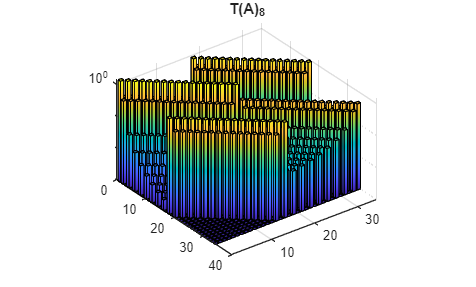

% Create  Toeplitz-Block form truncated to h=8 harmonics
h = 8;
A_tb = A.T_tb(h); % Toeplitz-Block form (full matrix)
% Visualize the structure
figure
barsurf(abs(A_tb),1e-3); 
title('T(A)_8');

A_four = F_tb(A,h) % Fourier form of PhasorArray A 

A_four =    0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0086 - 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0165 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0454 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.4056 + 0.0000i   0.5000 + 0.0000i
   1.5000 + 0.0000i   1.0000 + 0.0000i
  -0.4056 - 0.0000i   0.5000 - 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0454 - 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0165 - 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i


% For system with state dimension n=2 and period T=1
T = 1;
h = 10; % Truncation order
% Construct N operator in Toeplitz-Block form
Ntb = N_tb(size(A,1), h, T); 

lambda = A.HmqNEig(h,T,"fundamental")

lambda =    1.9060 + 0.0000i
  -0.9060 + 0.0000i


Q = PhasorArray.eye(2); % Positive definite Q(t)
P = lyap(A,Q,"T",T);

lyap : solved for h = 62, with residual 7.388789e-07


t=0:0.1:T;
Pt = evalTime(P,T,t);

B = [1;PhasorArray.sin]

B = 2x1x3 PhasorArray of double representing a 2x1 real-valued periodic matrix with 1 harmonics

Q = PhasorArray.eye(2)*10;
R = PhasorArray.eye(1);
K0 = PhasorArray([10,10]);
htrunc = 6; %initial truncation order for Riccati solution

[K_final, S_final] = RicHarmonicKlein(A, B, Q, R, K0,T,"autoUpdateh",true,"max_iter",50,"residualThreshold",1e-6,"htrunc",htrunc,"hmax",500)

Converged at iteration 9
Riccati residual norm: 2.37e-07


K_final = 1x2x157 PhasorArray of double representing a 1x2 real-valued periodic matrix with 78 harmonics

S_final = 2x2x155 PhasorArray of double representing a 2x2 real-valued periodic matrix with 77 harmonics

eig_closedloop=HmqNEig(A-B*K_final,20,T,"fundamental")

eig_closedloop =   -2.3237 + 0.0000i
  -3.4465 - 0.0000i


% TBLMI LQR Optimization Problem
hlmi = 20; %truncation order for LMI
hP = 10; %truncation order for P in LMI
ht = 10; %truncation order for A in LMI
% Define decision variable (periodic P via harmonics)
P = PhasorArray.ndsdpvar(2, 2, hP);
% Formulate LMI components
LMIvar11 = trunc(A,ht).'*P + P*trunc(A,ht)+ P.d(T) + Q;

LMIvar12 = P*B;
LMIvar22 = R;
% Convert to Toeplitz-Block form
P_tb = P.T_tb(hlmi); 
LMI_tb = [T_tb(LMIvar11, hlmi) , T_tb(LMIvar12, hlmi);
 T_tb(LMIvar12.', hlmi), T_tb(LMIvar22, hlmi)];
% Solve: maximize trace(P_0) subject to constraints
Constraints = [P_tb >= 0, LMI_tb >= 0];
Objective = -trace(P{:,:,0});%use P{i,j,k} to access kth phasor of P_{i,j}
sol = optimize(Constraints, Objective);


MOSEK Version 11.0.24 (Build date: 2025-6-25 11:19:55)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 63              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2 (scalarized: 43911)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - 

Psol = sdpval(P); % Extract solution as PhasorArray
K=inv(R)*B'*Psol % Optimal feedback

K = 1x2x23 PhasorArray of double representing a 1x2 real-valued periodic matrix with 11 harmonics

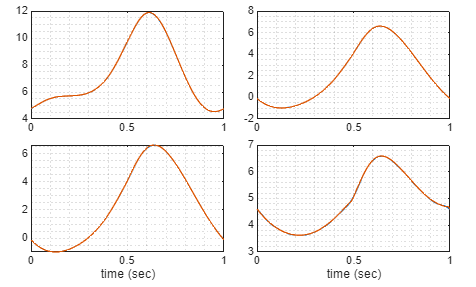

% Compare solutions
figure
plot(Psol, T, 0:T/100:T);
hold on;
plot(S_final, T, 0:T/100:T)

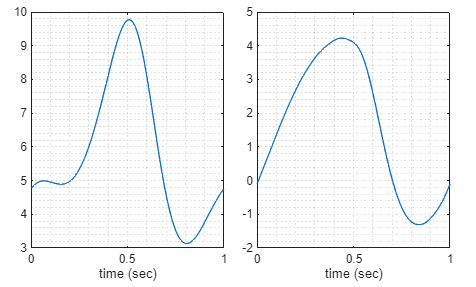

figure
plot(K, T, 0:T/100:T)

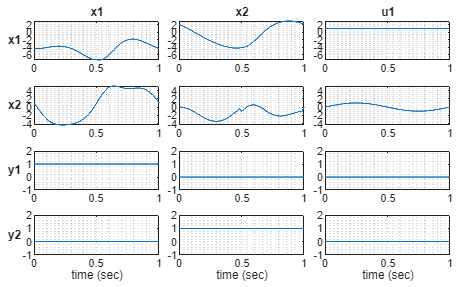

% Create LTP state-space system
C = PhasorArray.eye(2);
D = PhasorArray.zeros(2, 2);
sys = PhasorSS(A, B, C, D, T);
% Closed-loop system
sys_cl = feedback(sys, K_final);

figure
plot(sys_cl) %plot of matrix [A-BK,B;C,-DK]

% Simulate initial condition response
x0 = [1; 1];
t_sim = 0:T/100:5*T;

figure
initial(sys_cl, x0, t_sim);

Real valued LTP ss


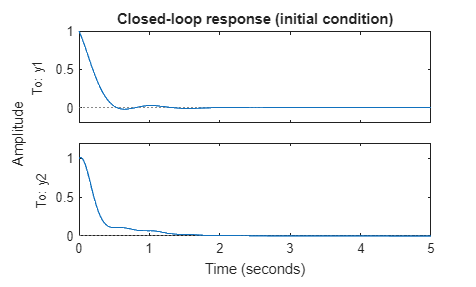

title('Closed-loop response (initial condition)')

figure
u= [1+PhasorArray.cos];
[y,t]=lsim(sys_cl,t_sim,u,x0);

Real valued LTP ss


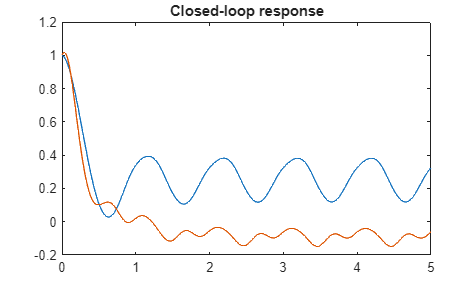

plot(t,y);
title('Closed-loop response')